clear all;
% Generate historical data
u = linspace(-2*pi, 2*pi, 1000)';
y = sin(u) + 0.1'; % Adding some nois


% Set parameters
lmax = 30;
delta = 10;
t = 100;
nmax = 20;

%{
stem(diag(S) / max(diag(S))); % Normalize for better visualization
xlabel('Index');
ylabel('Normalized Singular Value');
title('Singular Value Spectrum');

% Automated selection can be based on a threshold
threshold = 0.1; % Define a threshold for significant singular values
n = sum(diag(S) > threshold * max(diag(S)));
%}

% New inputs for future prediction
uf = linspace(2*pi, 3*pi, t)';

% Simulate actual future outputs (for example purposes)
actual_yf = sin(uf) + 0.1*randn(1,t)'; % Adding some noise for realism

% 
out = machovskyPredict(u, y, lmax, nmax, uf, delta,t);

k = 0


k = 1


k = 2


k = 3


k = 4


k = 5


k = 6


k = 7


k = 8


k = 9


k = 10



predicted = out(1,2:end)';

%whatdis = rmse(predicted,actual_yf);
xd = out(:)

xd =     0.0189
    0.0226
    0.0265
    0.0305
    0.0349
    0.0394
    0.0442
    0.0492
    0.0544
    0.0598



plot(xd)
hold on
plot(actual_yf)
hold off

As we can see this is not a great result, but this has to do with the fact that our system dimensions are not optimal. Let us define the conditions we need:

- The system S is controllable (LTI)

- We have a trajectory (u,y) that are an element of the system S

- u is persistently exciting of order delta+lmax+nmax

- row dim(Up) = row dim(Yp) = lmax

- row dim (Uf) = row dim(Yf) = delta

statenum = 3;
outputnum = 1;
inputnum = 2;
maxTime = 100;
input = [3;2];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
             x1        x2        x3
   x1    0.6404  -0.08278   0.05274
   x2   0.04716    0.7884  -0.07215
   x3  -0.01956  -0.04752    0.7045
 
  B = 
            u1       u2
   x1        0  -0.5141
   x2     -1.6    1.536
   x3  -0.8674  -0.4491
 
  C = 
            x1       x2       x3
   y1   0.1466  -0.1335  -0.7911
 
  D = 
            u1       u2
   y1  -0.1275        0
 
Sample time: unspecified
Discrete-time state-space model.


dssprop(state_space)

State-space properties: 
    "Number of states: 3"
    "Number of inputs: 2"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:3"    "A_cols:3"
    "B_rows:3"    "B_cols:2"
    "C_rows:1"    "C_cols:3"
    "D_rows:1"    "D_cols:2"

Max absolute eigen value: 0.78415
Eigen values of A: 
    0.7841
    0.6748
    0.6743



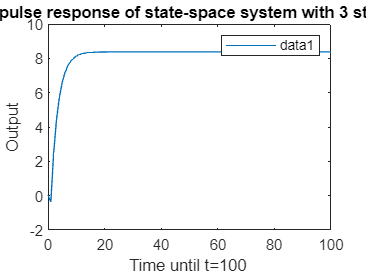


figure;
dssplot(state_space,maxTime,input);